# Uge 1: Definition og grundlæggende egenskaber ved Laplacetransformation og den inverse Laplacetransformation.  

Eksempler på anvendelse af Laplacetranformation til løsning af nogle simple begyndelsesværdiproblemer.

Forskydning i s - domænet (“e – reglen”). Differentiation af den transformerede (”t – reglen”).

Materiale. Signals, Systems and Transforms, fifth edition, side 360 – 369, 371 – 73, 381 – 82. + Appendix F side 773 –775

## Øvelsesopgaver

### Opgave 1

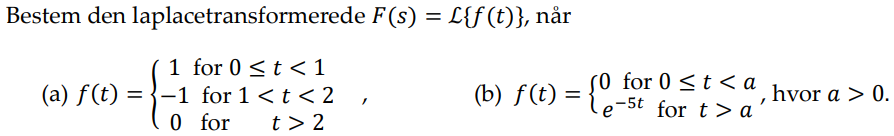

% First, set up the paths
setup_paths();

% Define symbolic variables
syms s t;

% Define the function f(t) = u(t) - 2u(t-1) + u(t-2)
% We'll use your library's functions to compute the Laplace transforms

% Calculate Laplace transform of u(t) with explanation
[F1, forklaring1] = ElektroMatBibTrinvis.enhedsTrinMedForklaring(0, t, s);
disp('Laplacetransformation af u(t):');
disp(F1);

% Calculate Laplace transform of u(t-1) with explanation
[F2, forklaring2] = ElektroMatBibTrinvis.enhedsTrinMedForklaring(1, t, s);
disp('Laplacetransformation af u(t-1):');
disp(F2);

% Calculate Laplace transform of u(t-2) with explanation
[F3, forklaring3] = ElektroMatBibTrinvis.enhedsTrinMedForklaring(2, t, s);
disp('Laplacetransformation af u(t-2):');
disp(F3);

% Combined Laplace transform for f(t) = u(t) - 2u(t-1) + u(t-2)
F = 1*F1 - 2*F2 + 1*F3;
F = simplify(F);

% Display the result
disp('Den samlede Laplacetransformation F(s):');
disp(F);

### Opgave 2

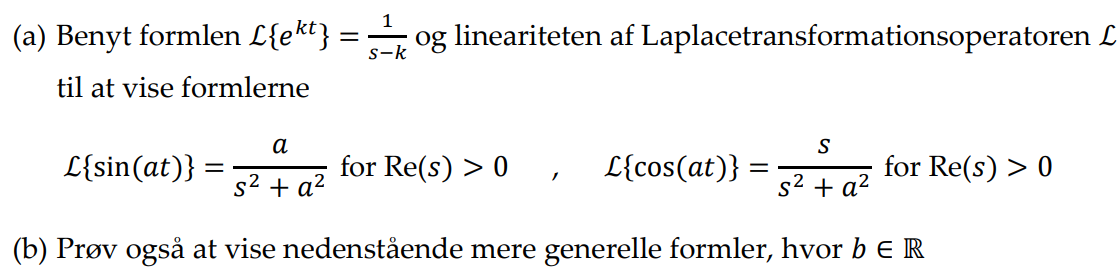

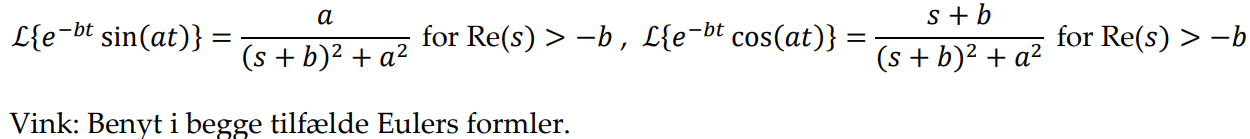

% Løsning af opgaven med ElektroMatBibTrinvis
syms s t a b;

% Del a: Vis formlen L{e^(kt)} = 1/(s-k)
disp('Del a:');
k = sym('k');
f1 = exp(k*t);
[F1, forklaring1] = ElektroMatBibTrinvis.laplaceMedForklaring(f1, t, s);
disp(['L{e^(kt)} = ' char(F1)]);

% Vis formler for sin(at) og cos(at)
f2 = sin(a*t);
f3 = cos(a*t);
[F2, forklaring2] = ElektroMatBibTrinvis.laplaceMedForklaring(f2, t, s);
[F3, forklaring3] = ElektroMatBibTrinvis.laplaceMedForklaring(f3, t, s);
disp(['L{sin(at)} = ' char(F2) ' for Re(s) > 0']);
disp(['L{cos(at)} = ' char(F3) ' for Re(s) > 0']);

% Del b: Bevis de mere generelle formler
disp('Del b:');
f4 = exp(-b*t)*sin(a*t);
f5 = exp(-b*t)*cos(a*t);
[F4, forklaring4] = ElektroMatBibTrinvis.laplaceMedForklaring(f4, t, s);
[F5, forklaring5] = ElektroMatBibTrinvis.laplaceMedForklaring(f5, t, s);
disp(['L{e^(-bt)sin(at)} = ' char(F4) ' for Re(s) > -b']);
disp(['L{e^(-bt)cos(at)} = ' char(F5) ' for Re(s) > -b']);

### Opgave 3

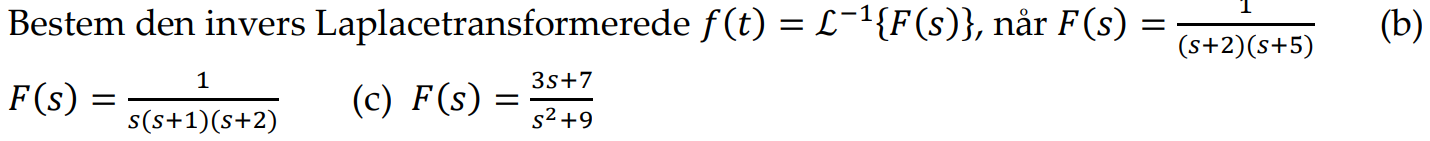

disp('F(s) = ');

F(s) = 


disp(F_b);

Unrecognized function or variable 'F_b'.


% Beregn invers Laplacetransformation med forklaring
[f_b, forklaring_b] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(F_b, s, t);

disp('f(t) = ');
disp(f_b);

% Opgave (c): F(s) = 1/(s(s+1)(s+2))
disp('===== OPGAVE (c) =====');
F_c = 1/(s*(s+1)*(s+2));
disp('F(s) = ');
disp(F_c);

% Beregn invers Laplacetransformation med forklaring
[f_c, forklaring_c] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(F_c, s, t);

disp('f(t) = ');
disp(f_c);

% Opgave (d): F(s) = (3s+7)/(s^2+9)
disp('===== OPGAVE (d) =====');
F_d = (3*s+7)/(s^2+9);
disp('F(s) = ');
disp(F_d);

% Beregn invers Laplacetransformation med forklaring
[f_d, forklaring_d] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(F_d, s, t);

disp('f(t) = ');
disp(f_d);

### Opgave 4